imds=imageDatastore("KTFEDataset\","IncludeSubfolders",true,"LabelSource","foldernames");
total_split= countEachLabel(imds)

total_split = 7×2 table
     Label      Count
    ________    _____

    Anger        252 
    Disgust      198 
    Fear         396 
    Happy        414 
    Neutral      376 
    Sad          433 
    Surprise     234 


num_images = length(imds.Labels)

num_images = 2303

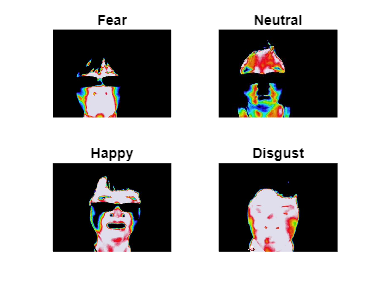



perm = randperm(num_images,4);
figure;
for idx=1:4
    subplot(2,2,idx);
    imshow(imread(imds.Files{perm(idx)}));
    title(sprintf('%s',imds.Labels(perm(idx))))
end


train_percent=0.80;
[imdsTrain,imdsTest]=splitEachLabel(imds,train_percent,'randomize');

valid_percent=0.1;
[imdsValid,imdsTrain]=splitEachLabel(imdsTrain,valid_percent,'randomize');

train_split=countEachLabel(imdsTrain)

train_split = 7×2 table
     Label      Count
    ________    _____

    Anger        182 
    Disgust      142 
    Fear         285 
    Happy        298 
    Neutral      271 
    Sad          311 
    Surprise     168 


valid_split=countEachLabel(imdsValid)

valid_split = 7×2 table
     Label      Count
    ________    _____

    Anger        20  
    Disgust      16  
    Fear         32  
    Happy        33  
    Neutral      30  
    Sad          35  
    Surprise     19  


test_split=countEachLabel(imdsTest)

test_split = 7×2 table
     Label      Count
    ________    _____

    Anger        50  
    Disgust      40  
    Fear         79  
    Happy        83  
    Neutral      75  
    Sad          87  
    Surprise     47  



imageInputSize = [227,227,3];
augmented_imdsTrain = augmentedImageDatastore(imageInputSize,imdsTrain);
augmented_imdsValid = augmentedImageDatastore(imageInputSize,imdsValid);
augmented_imdsTest = augmentedImageDatastore(imageInputSize,imdsTest);

actual_labels=imdsTest.Labels;